warning('off','all')

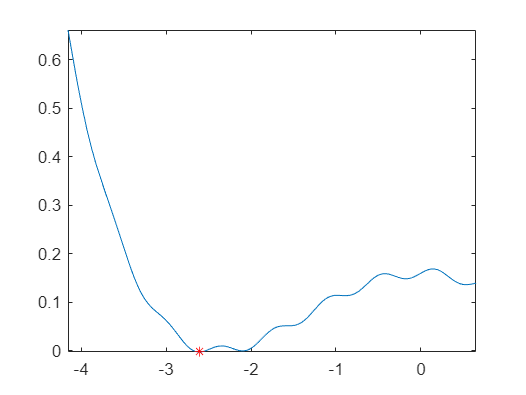

% DO QUIZU
func = @f;    % albo @g
Nmax = 10000;
epsilon = 0.0001;
start = -4.1557;
stop = 0.64976;
[min, i] = gold_div(start, stop, func, epsilon, Nmax);

dis('',start,stop,epsilon,Nmax,min,i)

Dla funkcji : 
Dla punktu startowego: -4.1557 i punktu końcowego : 0.64976 ,
dokładności rozwiązania: 0.0001
oraz maksymalnej liczby iteracji: 10000
 minimum funkcji, wyznaczone metodą złotego podziału to:
-2.6105
Wynik otrzymano w 23 iteracjach


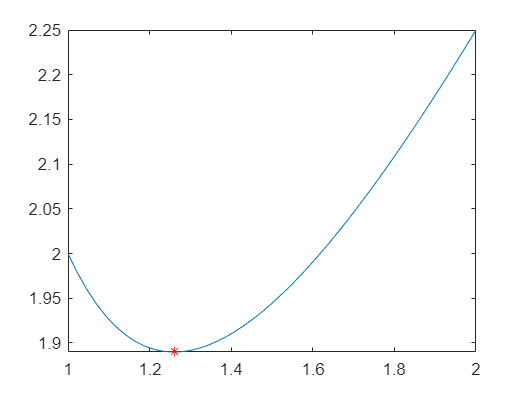

%FUNKCJA Z KONSPEKTU
[min, i] = gold_div(1, 2, @y, 0.01, 100);

dis('y',1,2,0.01,100,min,i)

Dla funkcji y: 
Dla punktu startowego: 1 i punktu końcowego : 2 ,
dokładności rozwiązania: 0.01
oraz maksymalnej liczby iteracji: 100
 minimum funkcji, wyznaczone metodą złotego podziału to:
1.2614
Wynik otrzymano w 10 iteracjach


Dla funkcji f: 
Dla punktu startowego: -4.1557 i punktu końcowego : 0.64976 ,
dokładności rozwiązania: 0.001
oraz maksymalnej liczby iteracji: 10000
 minimum funkcji, wyznaczone metodą złotego podziału to:
-2.6104
Wynik otrzymano w 18 iteracjach


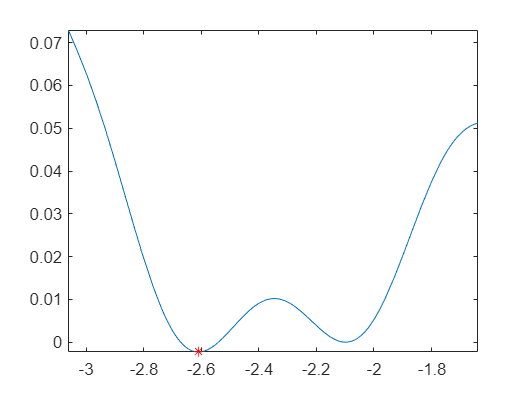

Dla funkcji f: 
Dla punktu startowego: -3.0629 i punktu końcowego : -1.6391 ,
dokładności rozwiązania: 0.001
oraz maksymalnej liczby iteracji: 10000
 minimum funkcji, wyznaczone metodą złotego podziału to:
-2.6107
Wynik otrzymano w 16 iteracjach


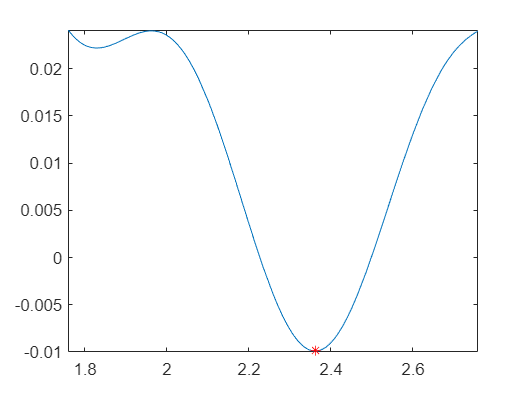

Dla funkcji f: 
Dla punktu startowego: 1.7594 i punktu końcowego : 2.7594 ,
dokładności rozwiązania: 0.001
oraz maksymalnej liczby iteracji: 10000
 minimum funkcji, wyznaczone metodą złotego podziału to:
2.3623
Wynik otrzymano w 15 iteracjach


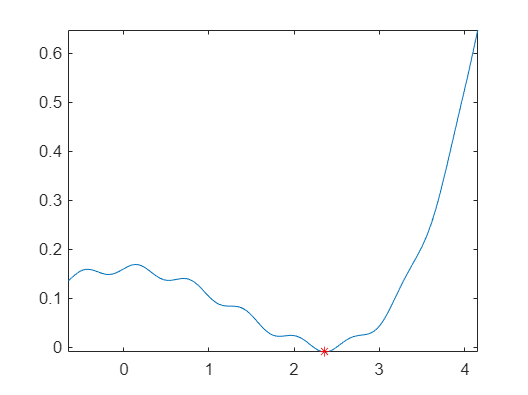

Dla funkcji f: 
Dla punktu startowego: -0.64976 i punktu końcowego : 4.1557 ,
dokładności rozwiązania: 0.001
oraz maksymalnej liczby iteracji: 10000
 minimum funkcji, wyznaczone metodą złotego podziału to:
2.3624
Wynik otrzymano w 18 iteracjach


%FUNKCJA F

Nmax = 10000;
epsilon = 0.001;

%przedziały z metody ekspancji dla punktów -8, -0.5, 1, 8
start = [-4.1557 -3.0629 1.7594 -0.64976];
stop = [0.64976 -1.6391 2.7594 4.1557];
for j=1:4 
    [min, i] = gold_div(start(j), stop(j), @f, epsilon, Nmax);
    dis('f',start(j),stop(j),epsilon,Nmax,min,i)
end

%FUNKCJA G

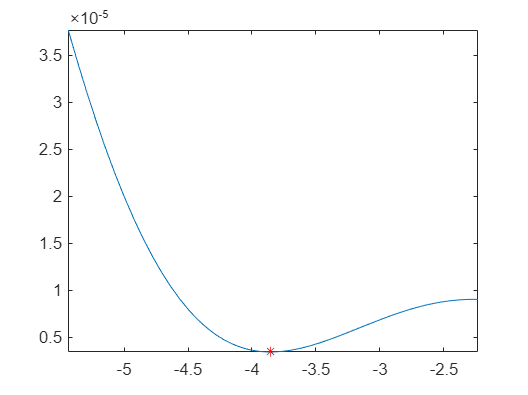

Dla funkcji g: 
Dla punktu startowego: -5.4371 i punktu końcowego : -2.2335 ,
dokładności rozwiązania: 0.0001
oraz maksymalnej liczby iteracji: 10000
 minimum funkcji, wyznaczone metodą złotego podziału to:
-3.8535
Wynik otrzymano w 22 iteracjach


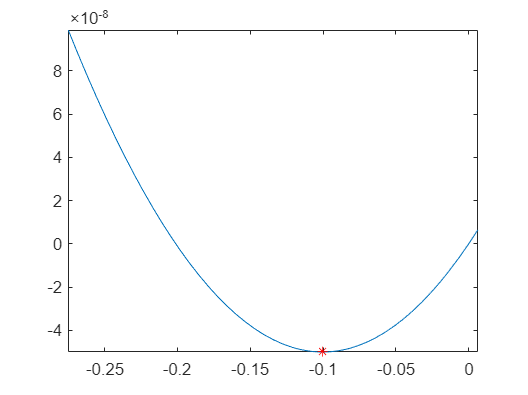

Dla funkcji g: 
Dla punktu startowego: -0.275 i punktu końcowego : 0.00625 ,
dokładności rozwiązania: 0.0001
oraz maksymalnej liczby iteracji: 10000
 minimum funkcji, wyznaczone metodą złotego podziału to:
-0.10031
Wynik otrzymano w 17 iteracjach


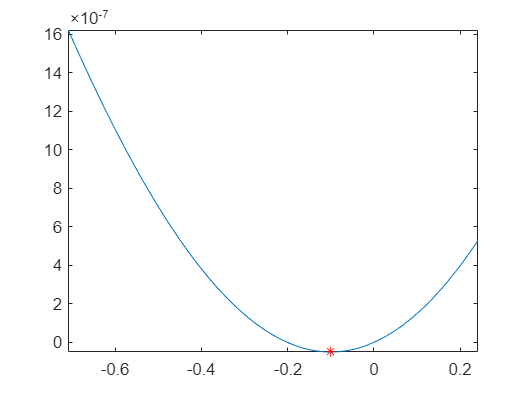

Dla funkcji g: 
Dla punktu startowego: -0.70859 i punktu końcowego : 0.24062 ,
dokładności rozwiązania: 0.0001
oraz maksymalnej liczby iteracji: 10000
 minimum funkcji, wyznaczone metodą złotego podziału to:
-0.10028
Wynik otrzymano w 20 iteracjach


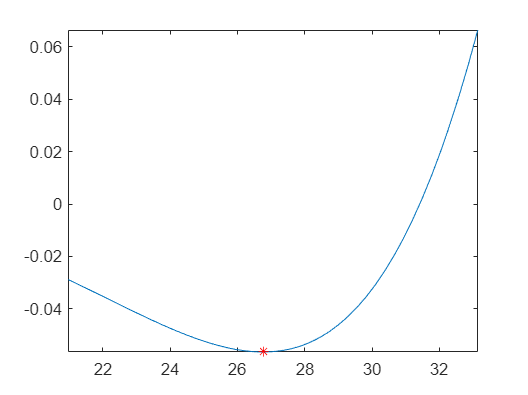

Dla funkcji g: 
Dla punktu startowego: 20.9746 i punktu końcowego : 33.1384 ,
dokładności rozwiązania: 0.0001
oraz maksymalnej liczby iteracji: 10000
 minimum funkcji, wyznaczone metodą złotego podziału to:
26.7605
Wynik otrzymano w 25 iteracjach



Nmax = 10000;
epsilon = 0.0001;

%przedziały z metody ekspancji dla punktów -8, -0.5, 1, 8
start = [-5.4371 -0.275 -0.70859 20.9746];
stop = [-2.2335 0.00625 0.24062 33.1384];
for j=1:4 
    [min, i] = gold_div(start(j), stop(j), @g, epsilon, Nmax);
    dis('g',start(j),stop(j),epsilon,Nmax,min,i)
end

function [x, i] = gold_div(start, stop, func, eps, Nmax)
    i = 0;
    alpha = (sqrt(5) - 1)/2;
    
    a_i = start;
    b_i = stop;
    c_i = stop - alpha*(stop - start);
    d_i = start + alpha*(stop - start);
    
    while abs(b_i - a_i) > eps && i < Nmax
       if func(c_i) < func(d_i)
            b_i = d_i;
            d_i = c_i;
            c_i = b_i - alpha * (b_i - a_i);
           
       else
            a_i = c_i;
            c_i = d_i;
            d_i = a_i + alpha*(b_i - a_i);    
       end
       i = i + 1;
       if i > Nmax
          fprintf("Unable to find minimum point in %d steps",N_max)
       end
       x = (a_i + b_i)/2;
    end
    figure()
    fplot(func,[start stop])
    hold on
    plot( x, func(x),'r*')
    hold off
    return;
end


function dis(f, a,b, epsilon, Nmax, result,i)
    disp('Dla funkcji ' + string(f) +': ')
    disp(['Dla punktu startowego: ', num2str(a), ' i punktu końcowego : ', num2str(b), ' ,'])
    disp(['dokładności rozwiązania: ', num2str(epsilon)]);
    disp(['oraz maksymalnej liczby iteracji: ', num2str(Nmax)]);
    disp(' minimum funkcji, wyznaczone metodą złotego podziału to:');
    disp([num2str(result)]);
    disp(['Wynik otrzymano w ', num2str(i), ' iteracjach']);
end

function kf=kf(x)

    kf=0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2;

end

function y=y(x)

    y=x+1/(x.^2);

end

function g=g(x)

    px = [-10 -5 0 5 10];

    py = [0.0001 -0.1 0 0.1 -0.0001];

    stopien = 5;

    W = polyfit(px, py, stopien);

    g = (0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x;

end